clear
close all
clc

Define polynomial contraction metric and ccm gain.

These are taken from the numerical example in "Nonlinear Stabilization via Control Contraction Metrics: a Pseudospectral Approach for Computing Geodesics" by K. Leung and I.R. Manchester

nx = 3;
xeq = zeros(nx,1);
x = [9;9;9];

W0 = [2.285714286 0.1428571429 -0.4285714286 ; 
      0.1428571429 1.571428571 0.2857142857;
      -0.4285714286 0.2857142857 1.142857143];
W1 = [0 -4.57142857142857 0 ; 
      -4.57142857142857 -0.571549759244019 0.857142857142854;
      0 0.857142857142854 0];
W2 = [0 0 0 ; 
      0 9.14297833067258 0;
      0 0 0];

W = @(x) (W0 + W1*x(1,:) + W2*x(1,:).^2);
dW = @(x) (W1 + 2*W2*x(1,:));

rho = @(x) (2 + 1.264*x(1,:) + 8.157*x(1,:).^2);

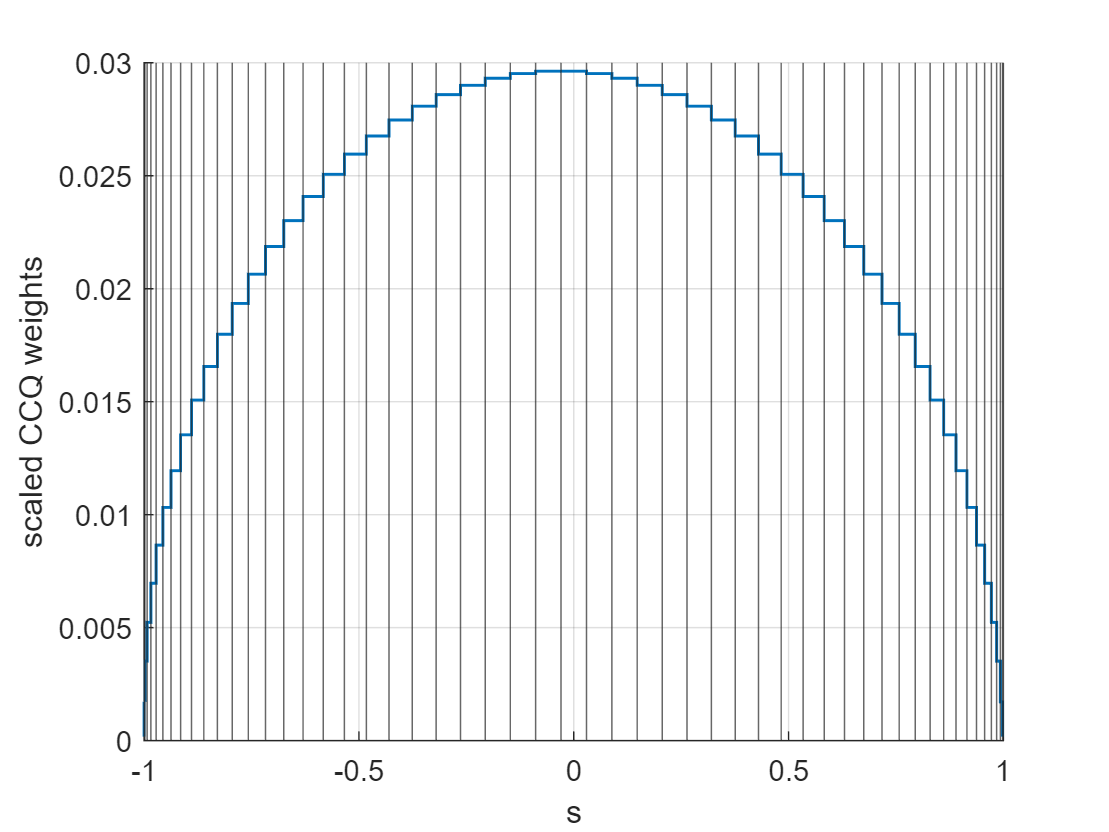

N = 4; % max chebyshev degree
num_cpnts = N+50; % number of collocation points

assert(N > 1, 'The geodesic path should be at least quadratic (N > 1)')

C0 = [0.5*(xeq+x), 0.5*(x-xeq), zeros(nx,N-1)]; % Initial guess: straight line connecting xeq and x

% Init CCQ scheme
[cpnts, weights] = ingredientsCCQ(0,1,num_cpnts);

% Plot
figure
xline(cpnts);
hold on
stairs(cpnts,weights,'LineWidth',1)
grid on
xlim([-1,1])
xlabel('s')
ylabel('scaled CCQ weights')

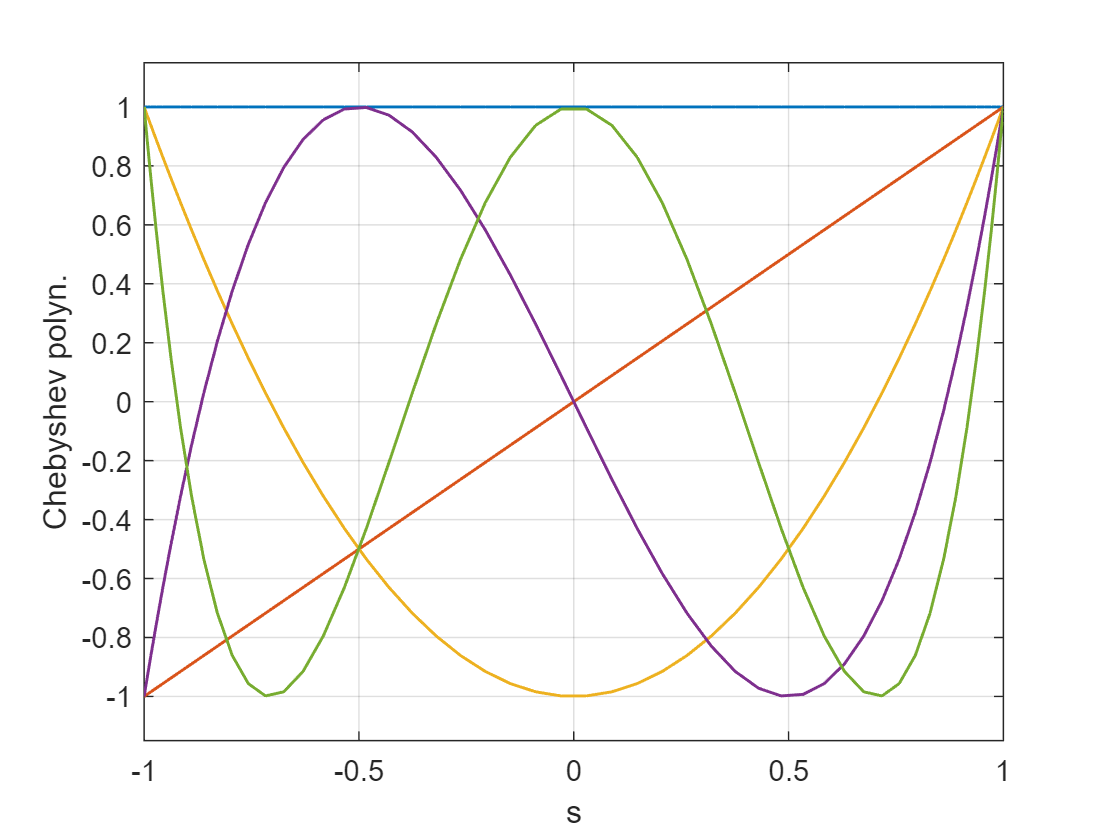


C = C0;

basis = chebyshevBase(0:N, cpnts);   % {N+1, num_cpnts}
dbasis = dchebyshevBase(0:N, cpnts); % {N+1, num_cpnts}

% Plot basis polynomials
figure
plot(cpnts,basis,'LineWidth',1)
grid on
xlim([-1,1])
ylim([-1.15,1.15])
xlabel('s')
ylabel('Chebyshev polyn.')

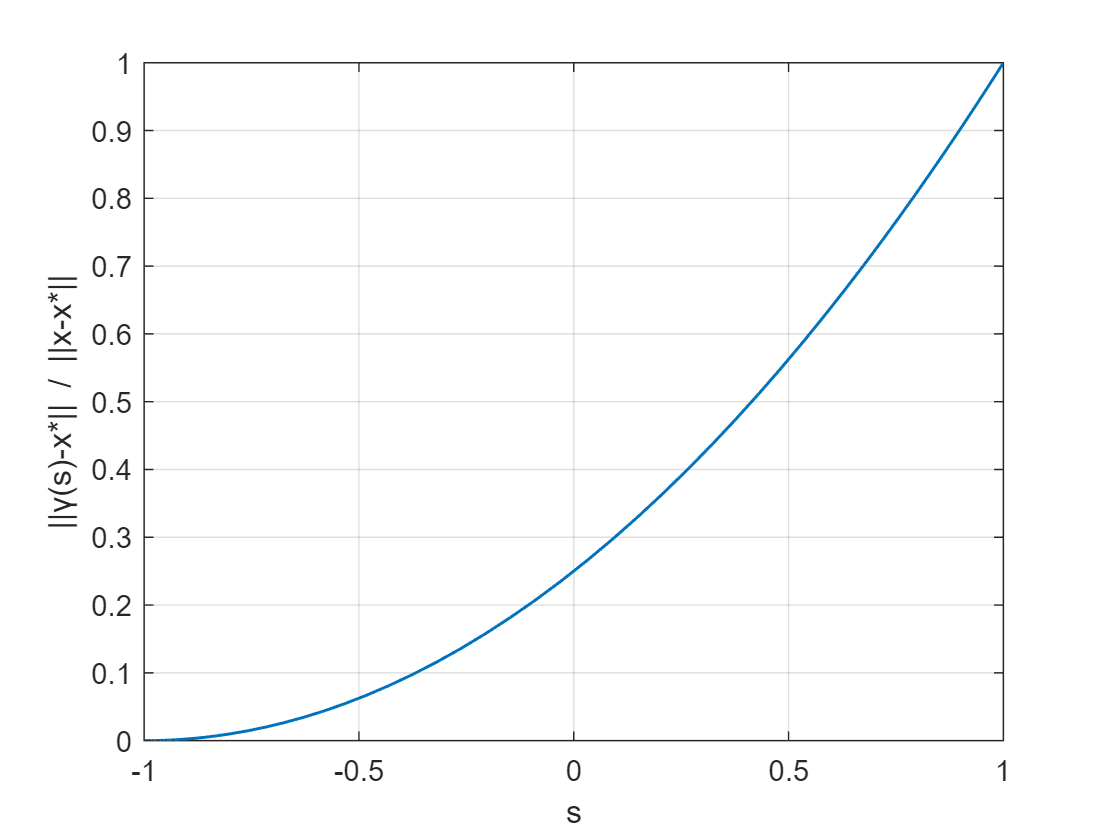


gammas = C*basis;           % {nx, num_cpnts}
dgammas = C*dbasis;         % {nx, num_cpnts}

% Plot distance to x
deltas = (gammas-xeq)/norm(x-xeq); % {nx, num_cpnts}
figure
plot(cpnts,deltas(1,:).^2 + deltas(2,:).^2 + deltas(3,:).^2,'LineWidth',1)
grid on
xlabel('s')
ylabel('||\gamma(s)-x*|| / ||x-x*||')
ylim([0,1])

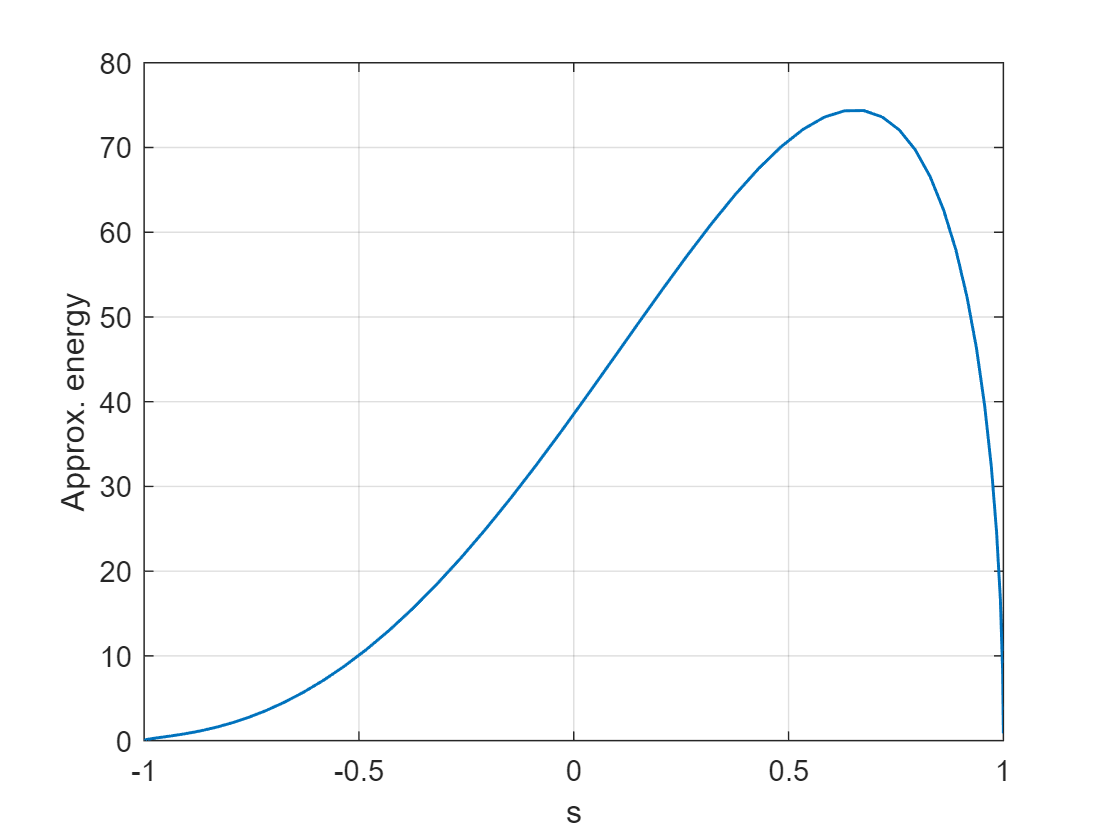


[E0, dE0, Es, dEs] = pathEnerg(W,dW,gammas,dgammas,basis,dbasis,weights);

% Plot energy
figure
plot(cpnts,Es,'LineWidth',1)
grid on
xlim([-1,1])
xlabel('s')
ylabel('Approx. energy')


% Boundary conditions
%    ! this formulation assumes that the decision matrix C is flattened to
%    a decision vector in row-major order. (MATLAB flattens column-major,
%    so must transpose first)
base1 = chebyshevT(0:N, -1);
base2 = chebyshevT(0:N, 1);
Aeq1 = base1;
Aeq2 = base2;
for i=1:nx-1
    Aeq1 = blkdiag(Aeq1, base1);
    Aeq2 = blkdiag(Aeq2, base2);
end
Aeq = [Aeq1; Aeq2];
beq = [xeq;x];

% Init decision variable
C0_T = C0';
cx = C0_T(:);

f = @(cx) ( energy_fun(W,dW,basis,dbasis,weights,nx, cx) );
opts = optimoptions('fmincon','Algorithm','sqp','MaxFunctionEvaluations',1e6);
copt = fmincon(f,cx,[],[],Aeq,beq,[],[],[],opts);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


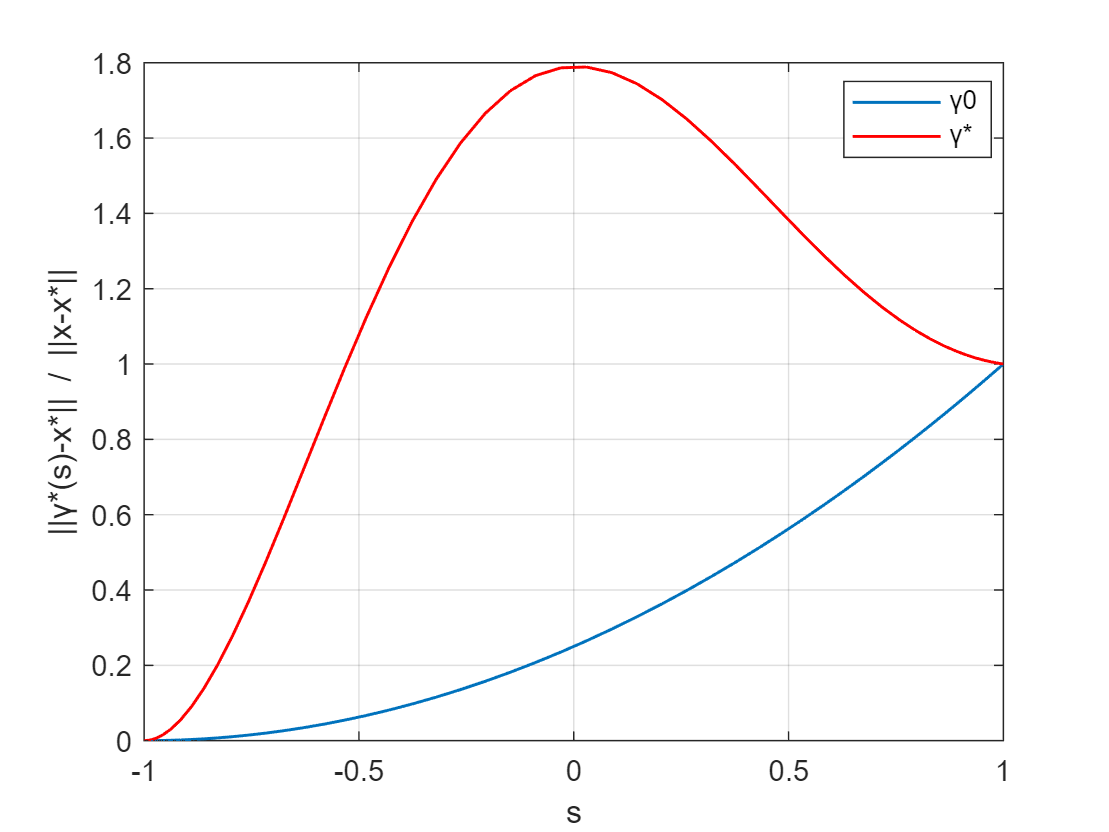

Copt = reshape(copt, [N+1,nx])';

gamma_opt = Copt*basis;
dgamma_opt = Copt*dbasis;

% Plot distance to x
deltas_opt = (gamma_opt-xeq)/norm(x-xeq); % {nx, num_cpnts}
figure
plot(cpnts,deltas(1,:).^2 + deltas(2,:).^2 + deltas(3,:).^2,'LineWidth',1)
hold on
plot(cpnts,deltas_opt(1,:).^2 + deltas_opt(2,:).^2 + deltas_opt(3,:).^2,'-r','LineWidth',1)
grid on
xlabel('s')
ylabel('||\gamma*(s)-x*|| / ||x-x*||')
legend('\gamma0','\gamma*','Location','best')

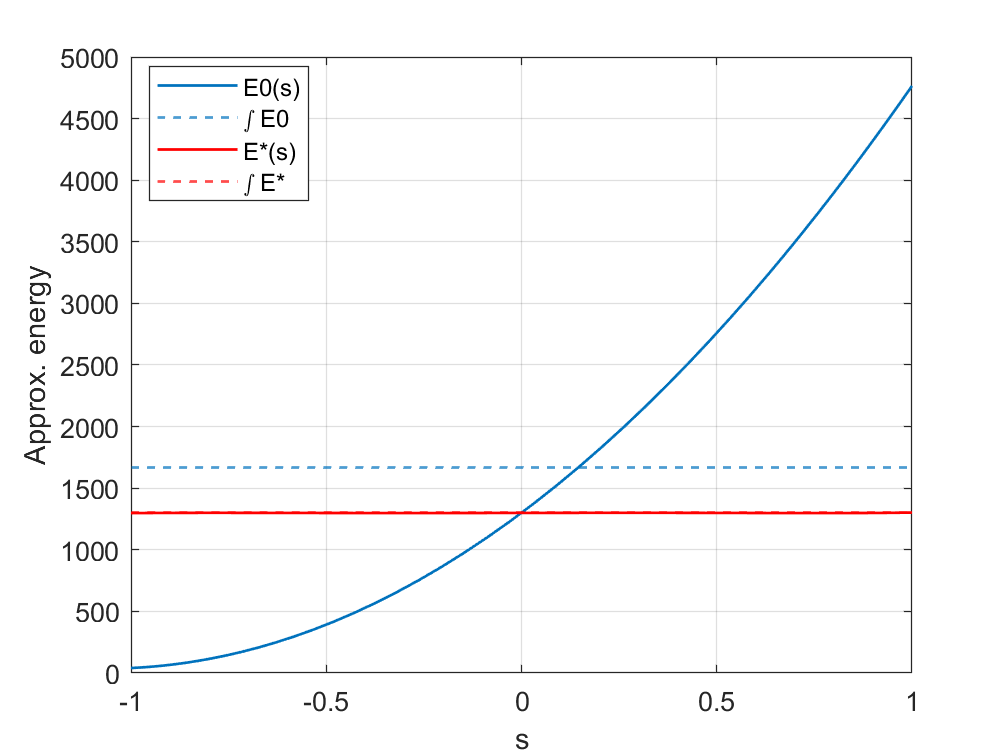


[~, ~, E0s, ~] = pathEnerg(W,dW,gammas,dgammas,basis,dbasis,ones(1,num_cpnts));
[E0, ~, ~, ~] = pathEnerg(W,dW,gammas,dgammas,basis,dbasis,weights);
[~, ~, Esopt, ~] = pathEnerg(W,dW,gamma_opt,dgamma_opt,basis,dbasis,ones(1,num_cpnts));
[Eopt, ~, ~, ~] = pathEnerg(W,dW,gamma_opt,dgamma_opt,basis,dbasis,weights);

% Plot energy
figure
plot(cpnts,E0s,'LineWidth',1,'Color',[0 0.4470 0.7410])
hold on
yline(E0,'--','Color',[0 0.4470 0.7410],'LineWidth',1);
plot(cpnts,Esopt,'-r','LineWidth',1)
yline(Eopt,'--r','LineWidth',1);
grid on
xlim([-1,1])
xlabel('s')
ylabel('Approx. energy')
legend('E0(s)','\int E0','E*(s)','\int E*','Location','best')

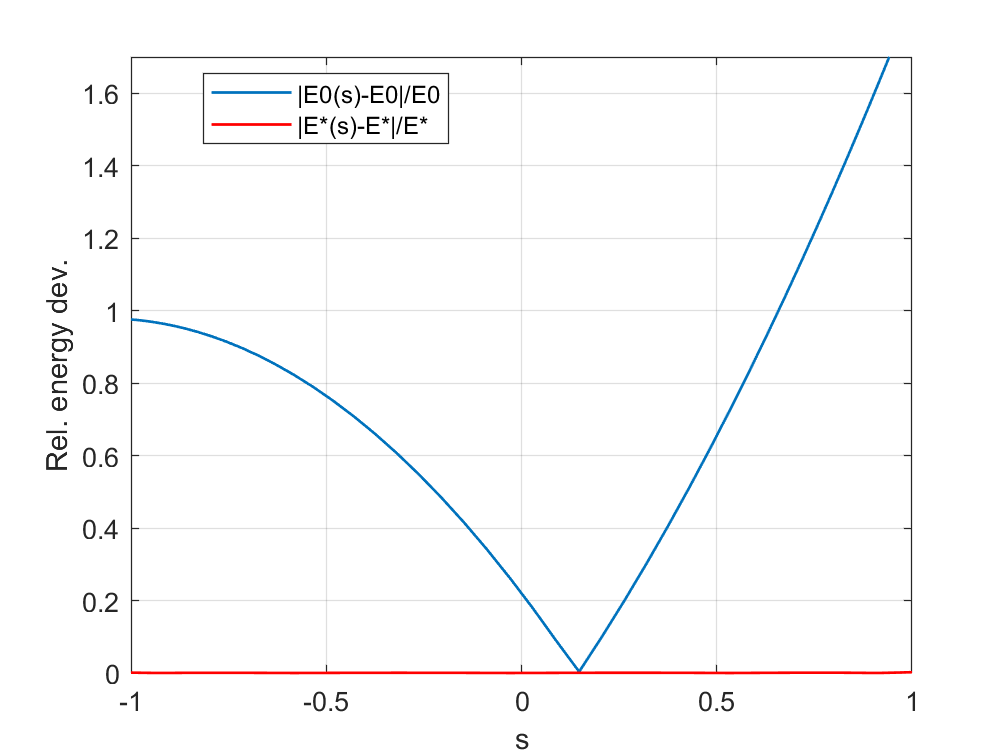


% Evaluate energy variation along paths (should be constant for a geodesic)
figure
plot(cpnts,abs(E0s-E0)/E0,'LineWidth',1)
hold on
plot(cpnts,abs(Esopt-Eopt)/Eopt,'-r','LineWidth',1)
grid on
xlim([-1,1])
ylim([0,1.7])
xlabel('s')
ylabel('Rel. energy dev.')
legend('|E0(s)-E0|/E0','|E*(s)-E*|/E*','Location','best')